close all
clc
clear

## **Esercizio 1.**

Genero un numero casuale compreso tra un certo range

n = 2 * randi([5, 10])

A1 = ones(n/2);
A2 = 2 * ones(n/2);
A3 = zeros(n/2);
A4 = ones(n/2);
A = [A1 A2
     A3 A4];


% Senza specificare niente otteniamo norma 2, altrimenti si specifica dopo
% la matrice
vec = [det(A), max(abs(eigs(A))), norm(A), norm(A, 2), norm(A, inf)];
t = array2table(vec, 'VariableNames', {'Determinante', 'Raggio spettrale', 'Norma 1', 'Norma 2', 'Norma infinito'});
disp(t);

close all
clc
clear

## Esercizio 2.

Ax = b;

A = 100 - 200 * rand(100);
while det(A) < 10e-10
    A = 100 - 200 * rand(100);
end
x = ones(100, 1);
b = A * x

b = 1.0e+03 *

    0.3456
    0.5651
   -0.1104
   -0.2070
    0.4398
   -0.8363
    0.9800
    0.4482
   -0.0404
   -0.9298
   -0.9227
    0.5385
   -0.4341
    0.3790
    0.5403


[U, b2] = gauss_p(A, b);

x1 = U\b2;

err_rel = norm(x1 - x) / norm(x)

err_rel = 4.3893e-15

fprintf('Errore relativo: %d', err_rel);

Errore relativo: 4.389300e-15

close all
clc
clear

## Esercizio 3.

Riscrivo la funzione

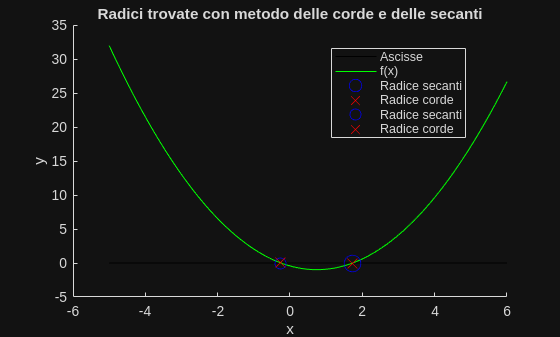

f = @(x) x .^ 2 - (sqrt(3) - 1 ./ 4) .* x - (sqrt(3) ./ 4);

f1 = @(x) 2 .*x - (sqrt(3) - 1 ./ 4);

x0 = 1;
x1 = 2;

[xs, ks] = secanti(f, x0, x1, 10e-5, 100);
[xc, kc] = corde(f, f1(x1), x0, 10e-5, 100);
[xs2, ks2] = secanti(f, -1, 1, 10e-5, 100);
[xc2, kc2] = corde(f, f1(-1), -1, 10e-5, 100);

x = linspace(-5, 6, 100);
figure;
hold on;

title("Radici trovate con metodo delle corde e delle secanti");
plot(x, zeros(size(x)), "-k", "DisplayName", "Ascisse");
plot(x, f(x), "-g", "DisplayName", "f(x)");
plot(xs, f(xs), "Ob", "DisplayName", "Radice secanti", "MarkerSize", 12);
plot(xc, f(xc), "Xr", "DisplayName", "Radice corde", "MarkerSize", 10);

plot(xs2, f(xs2), "Ob", "DisplayName", "Radice secanti", "MarkerSize", 8);
plot(xc2, f(xc2), "Xr", "DisplayName", "Radice corde", "MarkerSize", 10);

ylabel("y");
xlabel("x");

legend("Location", "best");

hold off;

function [U, b2] = gauss_p(A, b)

    % gauss_p: funzione che calcola la riduzione di Gauss con pivoting e 
    % prende in ingresso la matrice A e il vettore di termini noti b.
    % [U, b2] = gauss_p(A, b) restituisce la riduzione di Gauss, non i 
    % termini noti

    % Controlli preliminari sulle dimensioni di matrice, vettore e sul
    % determinante di A
    [m, n] = size(A);
    if m ~= n
        error("la matrice deve essere quadrata");
    end
    if size(b, 1) ~= n || size(b, 2) ~= 1
        error("b deve essere un vettore colonna con n righe");
    end
    if abs(det(A)) < 1e-10
        error("La matrice A è singolare");
    end


    for k = 1 : n-1

        [~, pos] = max(abs(A(k:n,k))); % Prendo le righe da k in giù nella colonna corrente
        % In pratica scarto il valore e prendo solo la posizione

        % Però ho il valore nel vettore che sto considerando, non della
        % matrice originale:
        l = pos + k - 1;

        % E poi scambio le righe:
        % Prendo la riga k E la riga l
        A([k l], :) = A([l k], :);
        b([k l]) = b([l k]);


        for i = k+1 : n
            m = A(i, k) / A(k, k);

            % Calcolo della nuova riga per ottenere una triangolare
            % inferiore
            A(i, :) = A(i, :) - m * A(k, :);

            b(i) = b(i) - m * b(k);
        end
    end

    % Assegno il valore corretto alle matrici da restituire
    U = A;
    b2 = b;
end

function [xc, kc] = corde(f, m, x0, tau, kmax)
    
    % corde: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0 
    %   [xc, kc] = corde(f, m, x0, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Controllo che il punto iniziale sia già una radice
    if(abs(f(x0)) < tau)
        xc = x0;
        kc = 1;
        return;
    end
    
    % Controllo che m non sia tendente a 0
    if abs(m) < tau
        error("Valore di m troppo vicino a 0");
    end

    % Inizio algoritmo iterativo da k a kmax
    for kc = 1 : kmax

        % Formula corde
        xc = x0 - f(x0) / m;

        % Condizioni di arresto
        if abs(f(xc)) < tau || abs(xc - x0) < tau * abs(x0)
            return;
        end

        % Aggiorno variabile
        x0 = xc;

    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    warning("Iterazioni massime raggiunte");

end

function [xs, ks] = secanti(f, x0, x1, tau, kmax)

    % secanti: metodo per trovare un'approssimazione della radice di 
    % f(x) = 0
    %   [x, k] = secanti(f, x0, x1, tau, kmax) restituisce l'approssimazione
    %   della radice e il numero di iterazioni effettuate.

    % Caso base: x0 è già una soluzione
    if abs(f(x0)) < tau
        xs = x0;
        ks = 0;
        return
    end


    % Inizio algoritmo iterativo da 1 a kmax con passo 1
    for ks = 1 : kmax

        % Controllo che i punti non siano gli stessi
        if x0 == x1
            error("Divisione per 0, modifica x0 e x1");
        end
        
        f0 = f(x0);
        f1 = f(x1);
        
        % Formula secanti
        m = (f1 - f0) / (x1 - x0);
        x_new = x1 - f1 / m;

        % Condizioni di arresto: se la soluzione non è variata
        % significativamente dall'iterazione precedente o se l'immagine
        % risulta abbastanza vicina a 0
        if abs(x_new - x1) < tau * abs(x1) || abs(f(x_new)) < tau
            xs = x_new;
            return;
        end

        % Aggiorno i punti
        x0 = x1;
        x1 = x_new;
    end

    % In caso esca dal ciclo significa che è stato raggiunto il numero
    % massimo di iterazioni senza che il punto trovato abbia raggiunto una
    % tolleranza accettabile
    xs = x_new;
    warning("Iterazioni massime raggiunte");
   
end